FUNCTION imageOut = rotate_image(imageIn)

Rotate input image so that its major axis is horizontal

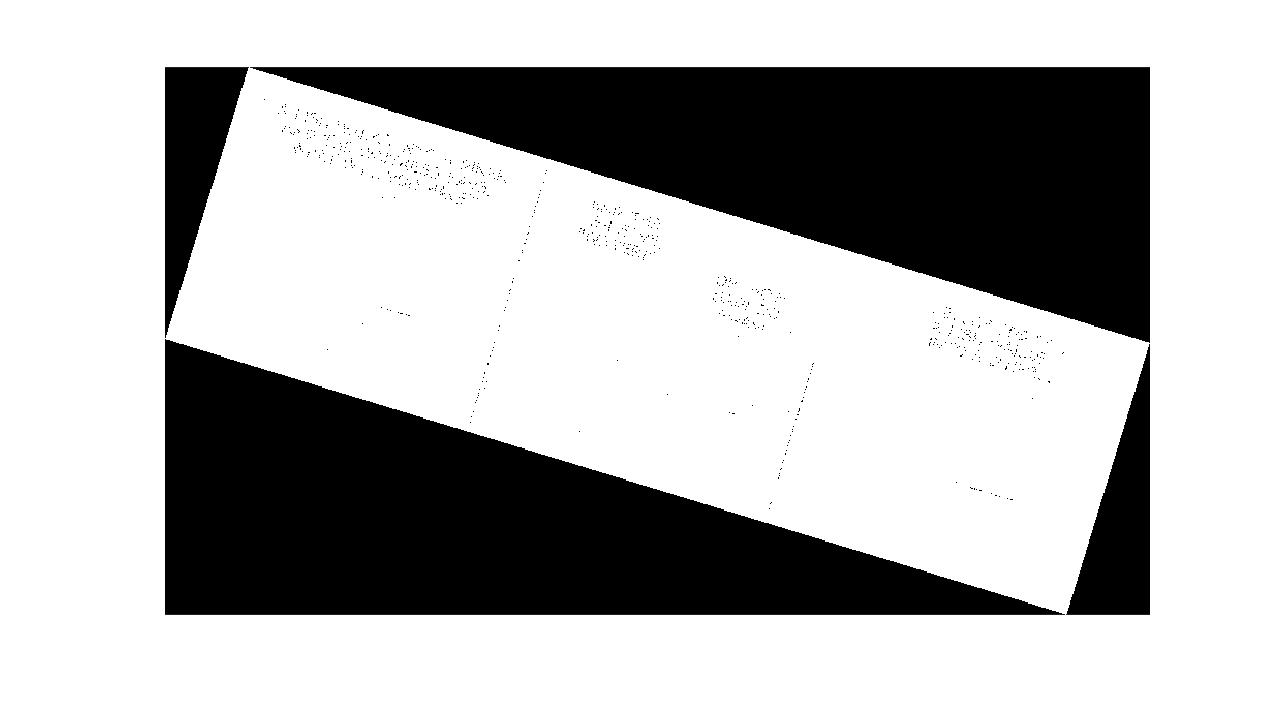

% function imageOut = rotate_image(imageIn)
imageIn=inputImages{imageNumber};

% Make a black & white version of the image
tempImage = imageIn;
if (size(imageIn,3)==3)
    tempImage=rgb2gray(imageIn);
end
bwImage=tempImage>(0.5/255);
image_show_resize(bwImage);

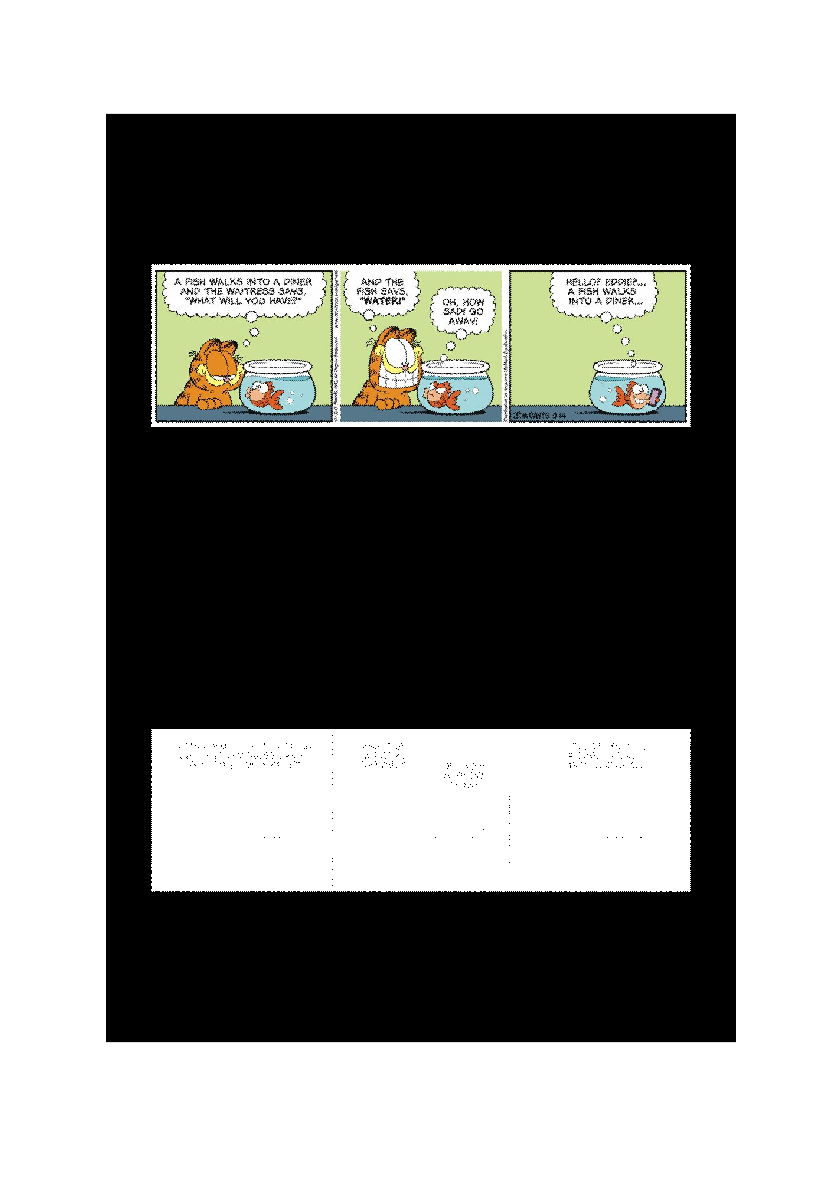


% Find the angle of the major axis to the horizontal
angle=cell2mat(struct2cell(regionprops(bwImage,'Orientation')));

% Rotate the BW and colour images to horizontal
imageIn=imrotate(imageIn,-angle);
bwImage=imrotate(bwImage,-angle);

figure,image_show_resize(imtile({imageIn, bwImage},'GridSize',[2 1]));

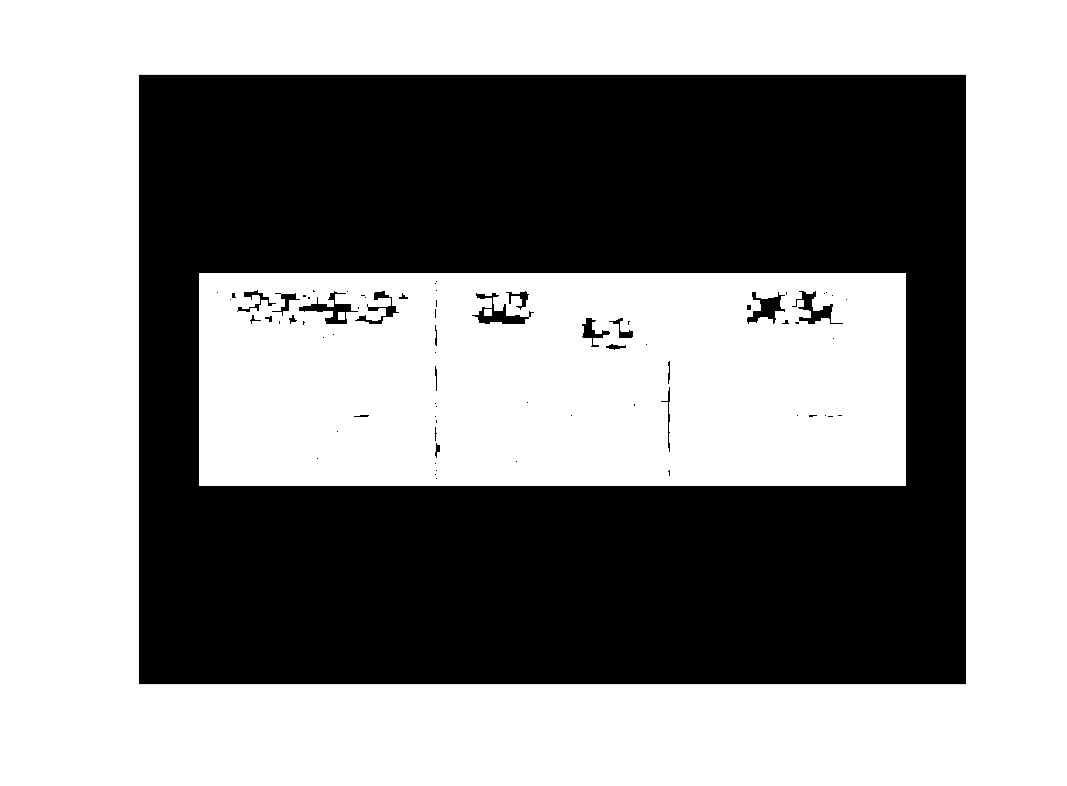


% Open then close the BW image to remove protrusions and hollows
bwImage=imopen(bwImage,strel('square',9));
hf=figure;imshow(bwImage);
[hf.Position(4),hf.Position(3),~]=size(bwImage);

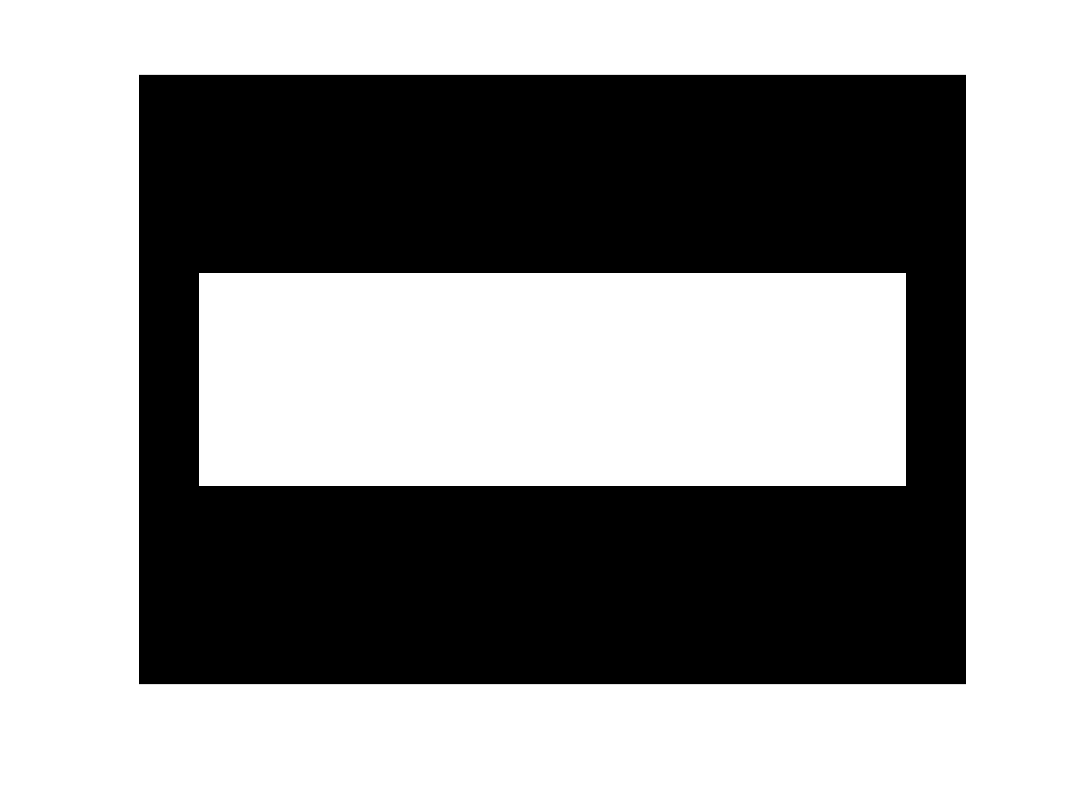


bwImage=imclose(bwImage,strel('square',21));
hf=figure;imshow(bwImage);
[hf.Position(4),hf.Position(3),~]=size(bwImage);

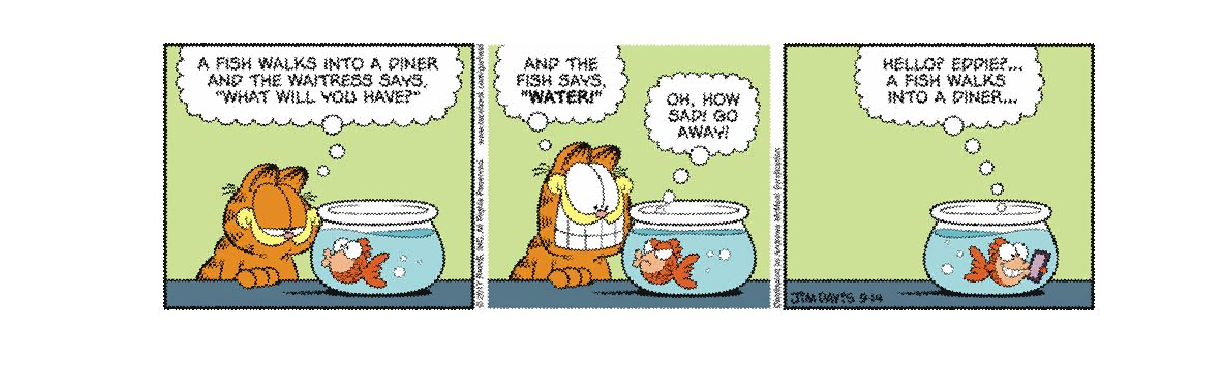


% Find a box around the BW image for cropping
cropBox=cell2mat(struct2cell(regionprops(bwImage,'BoundingBox')));

% Adjust the cropping box size so it excludes outer pixels
cropBox = cropBox - [0 0 1 1];

% Crop the rotated original image and return
rotatedImages{imageNumber} = imcrop(imageIn, cropBox);

image_show_resize(rotatedImages{imageNumber});